clear all

load EPCAPE_15min_data.mat

ET_Dcrit_15min = readtable('ET_Dcrit_15min.csv');
wetcritdiamavg15 = table2array(ET_Dcrit_15min(:,"Dta_critical_wet_fKDd_mean"))/10^3;
wetcritdiamstd15 = table2array(ET_Dcrit_15min(:,"Dta_critical_wet_fkDd_std"))/10^3;
ET_Dcrit_nativetime = readtable('ET_Dcrit_nativetime.csv')

ET_Dcrit_nativetime = 114528×5 table
            time             Dta      Dta_critical    Dta_critical_wet_fKDd    ClrCldHaz_class
    ____________________    ______    ____________    _____________________    _______________

    10-Mar-2023 22:38:16    139.48        NaN                 813.5                  NaN      
    10-Mar-2023 23:50:34    716.74        NaN                 15245                  NaN      
    10-Mar-2023 23:50:46    385.75        NaN                3741.4                  NaN      
    10-Mar-2023 23:51:10    158.49        NaN                985.28                  NaN      
    10-Mar-2023 23:51:13    186.84        NaN                1261.2                  NaN      
    10-Mar-2023 23:51:25    371.85        NaN                5696.7                  NaN      
    10-Mar-2023 23:51:36    83.6

wetcritdta = table2array(ET_Dcrit_nativetime(:,"Dta"));
wetcritcritdiam = table2array(ET_Dcrit_nativetime(:,"Dta_critical"));

time = ncread("EPCAPE_15mindata.nc", "time")

time = 35041×1 int64 column vector
                0
     899999996650
    1800000003349
    2700000000000
    3599999996650
    4500000003349
    5400000000000
    6299999996650
    7200000003349
    8100000000000
    8999999996650
    9900000003349
   10800000000000
   11699999996650
   12600000003349


ARM_LWC_15min = ncread("EPCAPE_15mindata.nc", "ARM_LWC");
FM120_LWC_15min = ncread("EPCAPE_15mindata.nc", "FM120_LWC");
SoledadLWC = ncread("EPCAPE_15mindata.nc", "FM120_LWC");
index = ncread("EPCAPE_15mindata.nc", "ClrCldHaz_class");
InCloudEventID_15min = ncread("EPCAPE_15mindata.nc", "InCloudEventID");
d = datetime(time, 'ConvertFrom',"epochtime", "Epoch", datetime(2023,2,15,00,00,00),"TicksPerSecond",10^9, "Format","default");
ARM_CBH_clean = ncread("EPCAPE_15mindata.nc", "ARM_CBH_clean");
FM120_DSD = ncread("EPCAPE_15mindata.nc", "FM120_DSD");
FM120_diam = ncread("EPCAPE_15mindata.nc", "FM120_diam");
MET_temp = ncread("EPCAPE_15mindata.nc", "MET_temp");

FM120_Nd = ncread("EPCAPE_15mindata.nc", "FM120_Nd");
cloudtimes1 = find(index == 1);
hazetimes2 = find(index == 2);



ans = 352.2500

ans = 236.2500


Piercloud = ARM_LWC_15min(cloudtimes1);
Soledadcloud = SoledadLWC(cloudtimes1);
cloudtime = d(cloudtimes1);
clouddiamavg = wetcritdiamavg15(cloudtimes1);

Pierhaze = ARM_LWC_15min(hazetimes2);
Soledadhaze = SoledadLWC(hazetimes2);
hazetime = d(hazetimes2);
hazediamavg = wetcritdiamavg15(hazetimes2);

ncdisp("EPCAPE_15mindata.nc")

Source:
           /Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/EPCAPE/Monthly FM-120 Files/EPCAPE_15mindata.nc
Format:
           netcdf4
Dimensions:
           time           = 35041
           AMS_species    = 5
           AMS_mz         = 472
           AMS_ptof_diam  = 60
           FM120_diam     = 30
           CE_singlelayer = 26
Variables:
    AMS_mass               
           Size:       5x35041
           Dimensions: AMS_species,time
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    AMS_massfrac           
           Size:       5x35041
           Dimensions: AMS_species,time
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    AMS_mzconc             
           Size:       472x35041
           Dimensions: AMS_mz,time
           Datatype:   double
           Attributes:
                       _FillValue = NaN
    AMS_mzORG              
           Size:       472x35041
       

time = ncread("EPCAPE_15mindata.nc", "time");
ARM_LWC_15min = ncread("EPCAPE_15mindata.nc", "ARM_LWC");
FM120_LWC_15min = ncread("EPCAPE_15mindata.nc", "FM120_LWC");
index = ncread("EPCAPE_15mindata.nc", "ClrCldHaz_class");


InCloudEventID_15min = ncread("EPCAPE_15mindata.nc", "InCloudEventID");
d = datetime(time, 'ConvertFrom',"epochtime", "Epoch", datetime(2023,2,15,00,00,00),"TicksPerSecond",10^9, "Format","default");
ARM_CBH_clean = ncread("EPCAPE_15mindata.nc", "ARM_CBH_clean");

%this is not in the table, and is calculated from the 15 minute index
totalcldhours = sum(index == 1)/4

totalcldhours = 352.2500

totalhazhours = sum(index == 2)/4

totalhazhours = 236.2500

totalcldsprhours = sum(index == 1 & month(d) >= 4 & month(d) <= 6)/4

totalcldsprhours = 106.2500

totalhazsprhours = sum(index == 2 & month(d) >= 4 & month(d) <= 6)/4

totalhazsprhours = 51.7500


totalcldsumhours = sum(index == 1 & month(d) >= 7 & month(d) <= 9)/4

totalcldsumhours = 185.2500

totalhazsumhours = sum(index == 2 & month(d) >= 7 & month(d) <= 9)/4

totalhazsumhours = 100.5000


totalcldfalhours = sum(index == 1 & month(d) >= 10 & month(d) <= 12)/4

totalcldfalhours = 47

totalhazfalhours = sum(index == 2 & month(d) >= 10 & month(d) <= 12)/4

totalhazfalhours = 49.5000


totalcldwinhours = sum(index == 1 & month(d) >= 1 & month(d) <= 3)/4

totalcldwinhours = 13.7500

totalhazwinhours = sum(index == 2 & month(d) >= 1 & month(d) <= 3)/4

totalhazwinhours = 34.5000


cloudtimes1 = find(index == 1)

cloudtimes1 =         2482
        2483
        2484
        2485
        2486
        2487
        2488
        2489
        2490
        2491
        2492
        2493
        2494
        2496
        5111


hazetimes2 = find(index == 2);

mean(AMS_mass_15min_EF(:,cloudtimes1),2,'omitmissing')

ans =     0.4334
    0.3558
    0.6113
    0.2356
    0.0706


std(AMS_mass_15min_EF(:,cloudtimes1),[],2,"omitmissing")

ans =     0.4192
    0.2902
    0.5912
    0.1832
    0.0623



mean(AMS_mass_15min_EF(:,hazetimes2),2,'omitmissing')

ans =     0.2169
    0.1009
    0.1990
    0.0927
    0.0334


std(AMS_mass_15min_EF(:,hazetimes2),[],2,"omitmissing")

ans =     0.2679
    0.1232
    0.2328
    0.1104
    0.0412



Piercloud = ARM_LWC_15min(cloudtimes1);
Soledadcloud = FM120_LWC_15min(cloudtimes1);
cloudtime = d(cloudtimes1);

Pierhaze = ARM_LWC_15min(hazetimes2);
Soledadhaze = FM120_LWC_15min(hazetimes2);
hazetime = d(hazetimes2);


%heightright = find(ARM_CBH_clean < 2000);
%ourpleHeightRight = ARM_CBH_clean < 2000 & index == 0 
%frHeightRight = heightright(ourpleHeightRight)
cbhtime = d(ARM_CBH_clean < 2000 & index == 0)

cbhtime = 8878×1 datetime array
   10-Mar-2023 22:44:59
   10-Mar-2023 23:00:00
   10-Mar-2023 23:15:00
   10-Mar-2023 23:29:59
   11-Mar-2023 02:29:59
   11-Mar-2023 03:00:00
   11-Mar-2023 03:14:59
   11-Mar-2023 03:30:00
   11-Mar-2023 04:44:59
   11-Mar-2023 05:45:00
   11-Mar-2023 06:00:00
   11-Mar-2023 06:14:59
   11-Mar-2023 06:30:00
   11-Mar-2023 06:45:00
   11-Mar-2023 06:59:59
   11-Mar-2023 07:15:00
   11-Mar-2023 07:30:00
   11-Mar-2023 07:44:59
   11-Mar-2023 08:00:00
   11-Mar-2023 08:15:00
   11-Mar-2023 08:29:59
   11-Mar-2023 08:45:00
   11-Mar-2023 09:00:00
   11-Mar-2023 09:14:59
   11-Mar-2023 09:30:00
   11-Mar-2023 09:45:00
   11-Mar-2023 09:59:59
   11-Mar-2023 10:15:00
   11-Mar-2023 10:30:00
   11-Mar-2023 10:44:59


cbhtimespr = month(cbhtime)  >= 4 & month(cbhtime)<= 6;
cbhtimesum = month(cbhtime)  >= 7 & month(cbhtime)<= 9;
cbhtimefal = month(cbhtime)  >= 10 & month(cbhtime)<= 12;
cbhtimewin = month(cbhtime)  >= 1 & month(cbhtime)<= 3;


ccbhtime = d(ARM_CBH_clean < 2000 & index == 1);

ccbhtime = 1169×1 datetime array
   12-Mar-2023 20:15:00
   12-Mar-2023 20:29:59
   12-Mar-2023 20:45:00
   12-Mar-2023 21:00:00
   12-Mar-2023 21:14:59
   12-Mar-2023 21:30:00
   12-Mar-2023 21:45:00
   12-Mar-2023 21:59:59
   12-Mar-2023 22:15:00
   12-Mar-2023 22:30:00
   12-Mar-2023 22:44:59
   12-Mar-2023 23:00:00
   12-Mar-2023 23:15:00
   12-Mar-2023 23:45:00
   09-Apr-2023 05:29:59
   09-Apr-2023 05:45:00
   09-Apr-2023 06:00:00
   09-Apr-2023 06:14:59
   09-Apr-2023 06:45:00
   09-Apr-2023 06:59:59
   09-Apr-2023 07:15:00
   09-Apr-2023 07:30:00
   09-Apr-2023 07:44:59
   09-Apr-2023 08:00:00
   09-Apr-2023 08:15:00
   09-Apr-2023 08:29:59
   09-Apr-2023 09:00:00
   09-Apr-2023 09:30:00
   09-Apr-2023 09:45:00
   09-Apr-2023 09:59:59


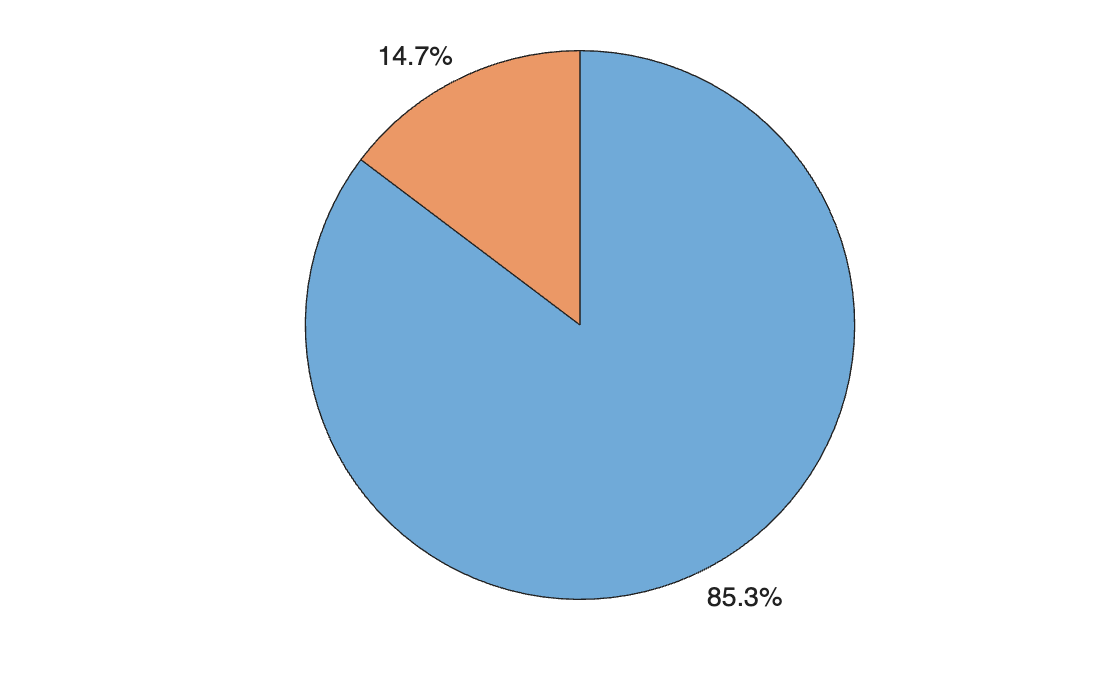

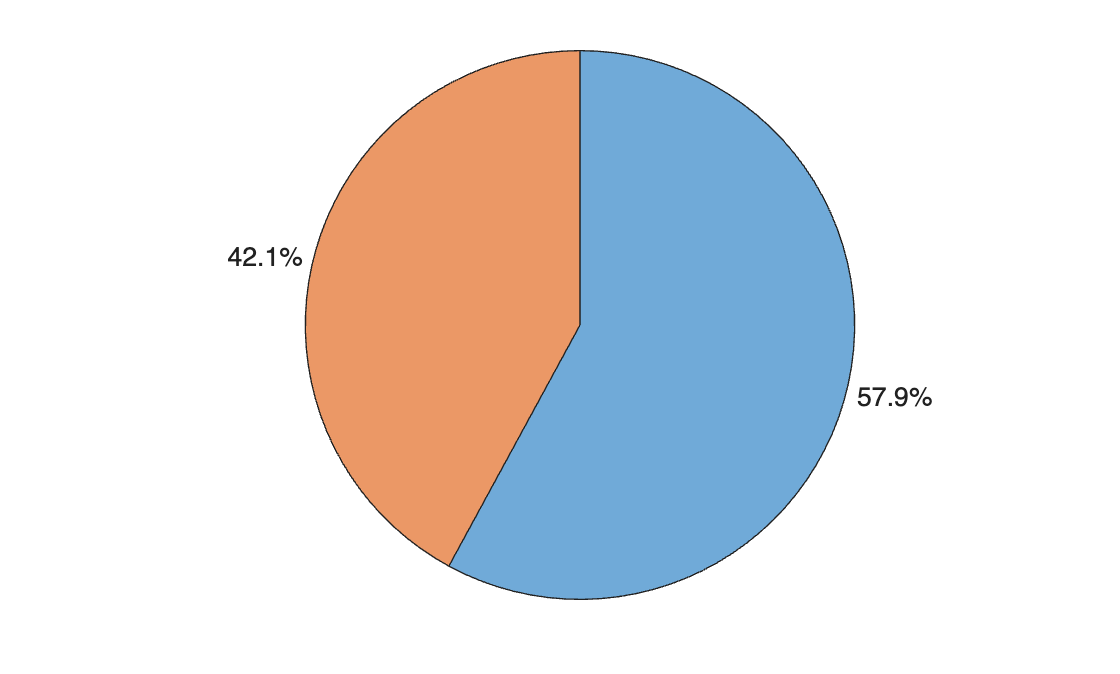

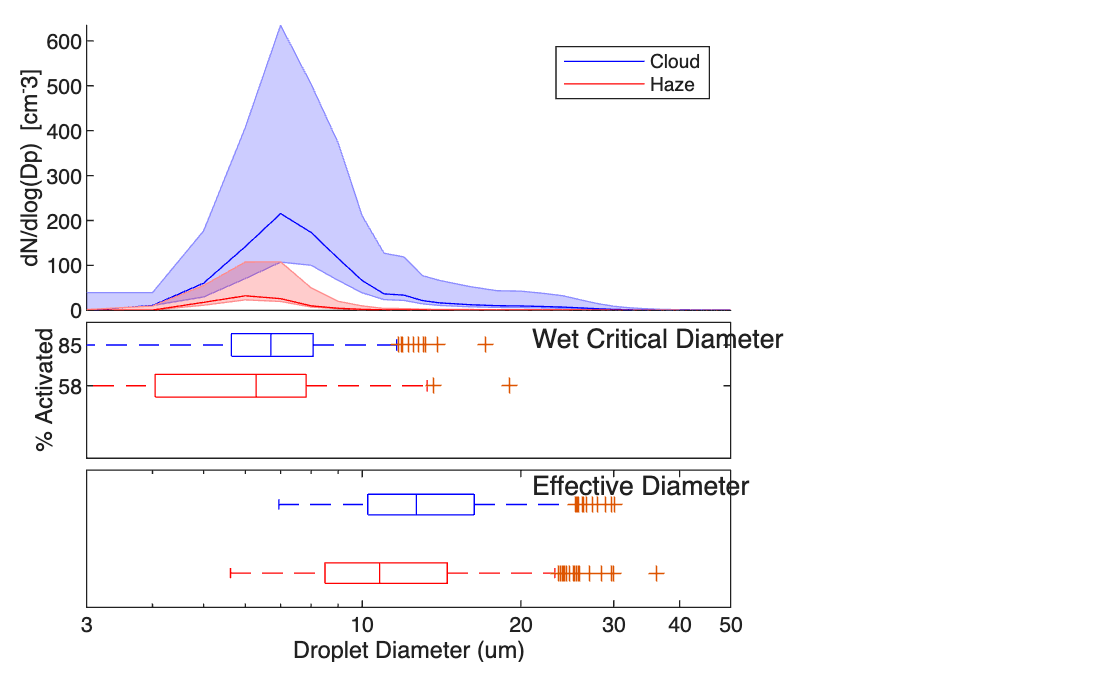

ccbhtimespr = month(ccbhtime)  >= 4 & month(ccbhtime)<= 6;
ccbhtimesum = month(ccbhtime)  >= 7 & month(ccbhtime)<= 9;
ccbhtimefal = month(ccbhtime)  >= 10 & month(ccbhtime)<= 12;
ccbhtimewin = month(ccbhtime)  >= 1 & month(ccbhtime)<= 3;


hcbhtime = d(ARM_CBH_clean < 2000 & index == 2);
hcbhtimespr = month(hcbhtime)  >= 4 & month(hcbhtime)<= 6;
hcbhtimesum = month(hcbhtime)  >= 7 & month(hcbhtime)<= 9;
hcbhtimefal = month(hcbhtime)  >= 10 & month(hcbhtime)<= 12;
hcbhtimewin = month(hcbhtime)  >= 1 & month(hcbhtime)<= 3;


CloudBaseHeight = ARM_CBH_clean(ARM_CBH_clean < 2000 & index == 0);
cloudscbh = ARM_CBH_clean(ARM_CBH_clean < 2000 & index == 1);
hazescbh = ARM_CBH_clean(ARM_CBH_clean < 2000 & index == 2);


%%indexes used in variables
zer = zeros(35041,1)

zer =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


springindex = (month(d) >= 4 & month(d) <= 6);
zerspringcld = zer;
zerspringcld(cloudtimes1) = 1;
zerspringhaz = zer;
zerspringhaz(hazetimes2) = 1;
springindexcld = find((springindex .* zerspringcld) == 1);
springindexhaz = find((springindex .* zerspringhaz) == 1);

summerindex = (month(d) >= 7 & month(d) <= 9);
zersummercld = zer;
zersummercld(cloudtimes1) = 1;
zersummerhaz = zer;
zersummerhaz(hazetimes2) = 1;
summerindexcld = find((summerindex .* zersummercld) == 1)

summerindexcld =        13112
       13113
       13114
       13115
       13200
       13204
       13205
       13206
       13207
       13208
       13209
       13210
       13211
       13212
       13213


summerindexhaz = find((summerindex .* zersummerhaz) == 1);

fallindex = (month(d) >= 10 & month(d) <= 12);
zerfallcld = zer;
zerfallcld(cloudtimes1) = 1;
zerfallhaz = zer;
zerfallhaz(hazetimes2) = 1;
fallindexcld = find((fallindex .* zerfallcld) == 1)

fallindexcld =        22209
       22210
       22211
       22212
       22213
       22214
       22217
       22218
       22219
       22220
       22221
       22612
       22613
       22623
       22624


fallindexhaz = find((fallindex .* zerfallhaz) == 1);

winterindex = (month(d) >= 1 & month(d) <= 3);
zerwintercld = zer;
zerwintercld(cloudtimes1) = 1;
zerwinterhaz = zer;
zerwinterhaz(hazetimes2) = 1;
winterindexcld = find((winterindex .* zerwintercld) == 1)

winterindexcld =         2482
        2483
        2484
        2485
        2486
        2487
        2488
        2489
        2490
        2491
        2492
        2493
        2494
        2496
       32487


winterindexhaz = find((winterindex .* zerwinterhaz) == 1);

%should, per season, end up with four sets, then those get inputted into
%the code prior and i should end up with six sets per season that get onto
%four charts. 

wetcritdiamavg15;


%WCD activites
wcdsprindcld = find(((month(nativetime) >= 4 & month(nativetime) <= 6).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 1)) ==1) ;
wcdsumindcld = find(((month(nativetime) >= 7 & month(nativetime) <=  9).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 1)) == 1);
wcdfalindcld = find(((month(nativetime) >= 10 & month(nativetime) <= 12).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 1)) ==1);
wcdwintindcld = find(((month(nativetime) >= 1 & month(nativetime) <= 3).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 1))==1);

sum(month(nativetime) >= 1 & month(nativetime) <= 3 & table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) ==1)

ans = 1203

find(wetcritcritdiam(month(nativetime) >= 1 & month(nativetime) <= 3 & table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) ==1) ==0)


ans =

  0×1 empty double column vector




wcdsprindhaz = find(((month(nativetime) >= 4 & month(nativetime) <= 6).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 2)) ==1) ;
wcdsumindhaz = find(((month(nativetime) >= 7 & month(nativetime) <=  9).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 2))==1);
wcdfalindhaz = find(((month(nativetime) >= 10 & month(nativetime) <= 12).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 2))==1);
wcdwintindhaz = find(((month(nativetime) >= 1 & month(nativetime) <= 3).*(table2array(ET_Dcrit_nativetime(:,"ClrCldHaz_class")) == 2))==1);


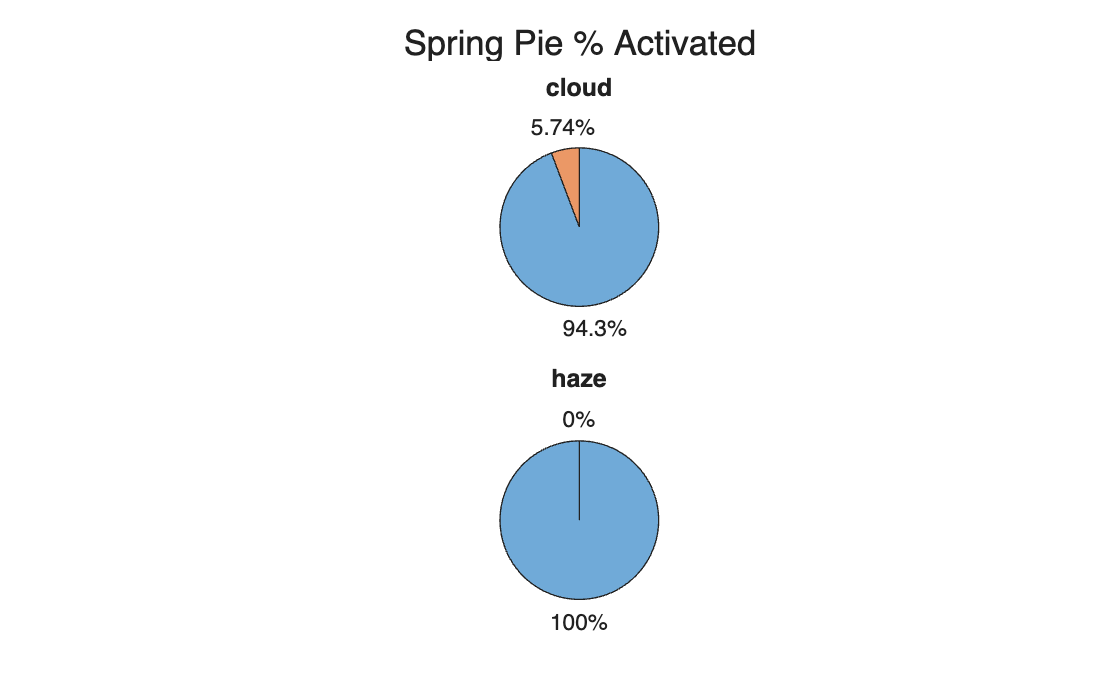


clf
Dtacld = wetcritdta(wcdsprindcld);
Dtacrit_cld = wetcritcritdiam(wcdsprindcld);
keep_idx = ~isnan(Dtacld) & ~isnan(Dtacrit_cld);
Dtacld_clean = Dtacld(keep_idx);
Dtacrit_cld_clean = Dtacrit_cld(keep_idx);
NotActivatedNumber = length(find(Dtacld_clean <= Dtacrit_cld_clean));
ActivatedNumber = length(find(Dtacld_clean > Dtacrit_cld_clean));
PercentActivatedCloud = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

Dtahaz = wetcritdta(wcdsprindhaz);
Dtacrit_haz = wetcritcritdiam(wcdsprindhaz);
keep_idx = ~isnan(Dtahaz) & ~isnan(Dtacrit_haz);
Dtahaz_clean = Dtahaz(keep_idx);
Dtacrit_haz_clean = Dtacrit_haz(keep_idx);
NotActivatedNumber = length(find(Dtahaz_clean <= Dtacrit_haz_clean));
ActivatedNumber = length(find(Dtahaz_clean > Dtacrit_haz_clean));
PercentActivatedHaze = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

tbig = tiledlayout('vertical');
nexttile
pc = piechart([PercentActivatedCloud/100 1-(PercentActivatedCloud/100)]);
sprcldactivate = round(pc.Proportions(1,1)*100,0);
title('cloud')
nexttile
ph = piechart([PercentActivatedHaze/100 1-(PercentActivatedHaze/100)]);
sprhazactivate = round(ph.Proportions(1,1)*100,0);
title('haze')

title(tbig,'Spring Pie % Activated')

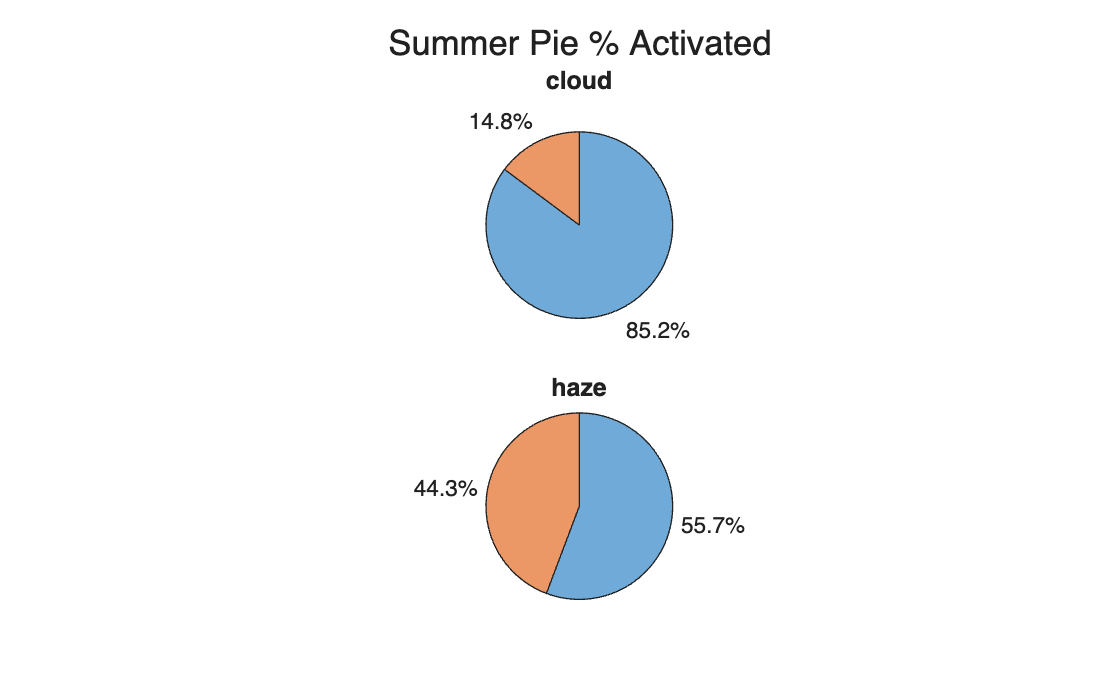

clf
Dtacld = wetcritdta(wcdsumindcld);
Dtacrit_cld = wetcritcritdiam(wcdsumindcld);
keep_idx = ~isnan(Dtacld) & ~isnan(Dtacrit_cld);
Dtacld_clean = Dtacld(keep_idx);
Dtacrit_cld_clean = Dtacrit_cld(keep_idx);
NotActivatedNumber = length(find(Dtacld_clean <= Dtacrit_cld_clean));
ActivatedNumber = length(find(Dtacld_clean > Dtacrit_cld_clean));
PercentActivatedCloud = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

Dtahaz = wetcritdta(wcdsumindhaz);
Dtacrit_haz = wetcritcritdiam(wcdsumindhaz);
keep_idx = ~isnan(Dtahaz) & ~isnan(Dtacrit_haz);
Dtahaz_clean = Dtahaz(keep_idx);
Dtacrit_haz_clean = Dtacrit_haz(keep_idx);
NotActivatedNumber = length(find(Dtahaz_clean <= Dtacrit_haz_clean));
ActivatedNumber = length(find(Dtahaz_clean > Dtacrit_haz_clean));
PercentActivatedHaze = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

tbig2 = tiledlayout('vertical');
nexttile
pc = piechart([PercentActivatedCloud/100 1-(PercentActivatedCloud/100)]);
sumcldactivate = round(pc.Proportions(1,1)*100,0);
title('cloud')
nexttile
ph = piechart([PercentActivatedHaze/100 1-(PercentActivatedHaze/100)]);
sumhazactivate = round(ph.Proportions(1,1)*100,0);
title('haze')

title(tbig2,'Summer Pie % Activated')

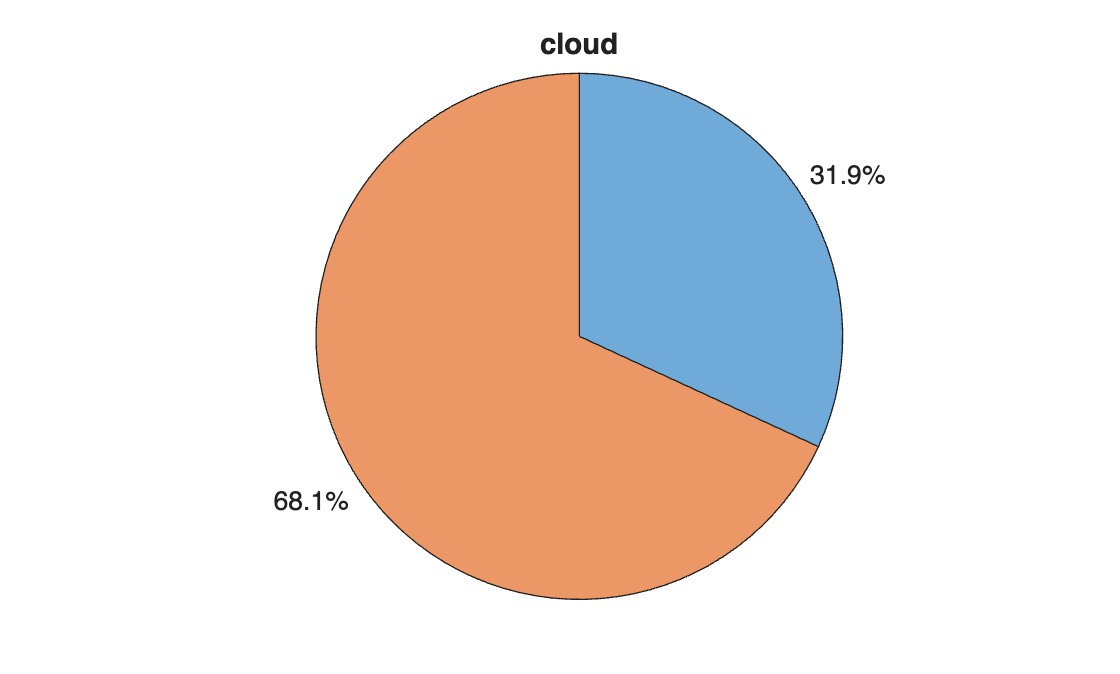

clf
Dtacld = wetcritdta(wcdfalindcld);
Dtacrit_cld = wetcritcritdiam(wcdfalindcld);
keep_idx = ~isnan(Dtacld) & ~isnan(Dtacrit_cld);
find(~isnan(Dtacrit_cld));
Dtacld_clean = Dtacld(keep_idx);
Dtacrit_cld_clean = Dtacrit_cld(keep_idx);
NotActivatedNumber = length(find(Dtacld_clean <= Dtacrit_cld_clean));
ActivatedNumber = length(find(Dtacld_clean > Dtacrit_cld_clean));
PercentActivatedCloud = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

Dtahaz = wetcritdta(wcdfalindhaz);
Dtacrit_haz = wetcritcritdiam(wcdfalindhaz);
keep_idx = ~isnan(Dtahaz) & ~isnan(Dtacrit_haz);
Dtahaz_clean = Dtahaz(keep_idx);
Dtacrit_haz_clean = Dtacrit_haz(keep_idx);
NotActivatedNumber = length(find(Dtahaz_clean <= Dtacrit_haz_clean));
ActivatedNumber = length(find(Dtahaz_clean > Dtacrit_haz_clean));
PercentActivatedHaze = (ActivatedNumber / (ActivatedNumber + NotActivatedNumber))*100;

tbig3 = tiledlayout('vertical');
nexttile
pc = piechart([PercentActivatedCloud/100 1-(PercentActivatedCloud/100)]);
falcldactivate = round(pc.Proportions(1,1)*100,0);
title('cloud')

radfiles=dir("/Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/EPCAPE/Monthly FM-120 Files/20*")

radfiles = 13×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


t5min = [];
LWC = [];
for j = 1:length(radfiles)
    file=fullfile(radfiles(j).folder,radfiles(j).name);
    tbl = readtable(file);
    LWC = [LWC;tbl.LWC_g_m_3_];
    t5min = [t5min;tbl.Var1];
end


avgvis = zeros(90011,1);

tbl1min = readtable("msd_visibility_20230224-20230719.csv")

tbl1min = 10015934×2 table
       datetime_GMT_       visibility_m_
    ___________________    _____________

    2023-02-24 00:00:01        40556    
    2023-02-24 00:00:02        40615    
    2023-02-24 00:00:03        40799    
    2023-02-24 00:00:04        40725    
    2023-02-24 00:00:06        40678    
    2023-02-24 00:00:07        40713    
    2023-02-24 00:00:08        40678    
    2023-02-24 00:00:09        40461    
    2023-02-24 00:00:10        40504    
    2023-02-24 00:00:11        40488    
    2023-02-24 00:00:12        40604    
    2023-02-24 00:00:14        40792    
    2023-02-24 00:00:15        40722    
    2023-02-24 00:00:16        40557    
    2023-02-24 00:00:17        40437    
    2023-02-24 00:00:18        40450    


tbl2min = readtable("msd_visibility_20230719-20240214.csv")

tbl2min = 14630325×2 table
       datetime_GMT_       visibility_m_
    ___________________    _____________

    2023-07-19 04:00:01        12731    
    2023-07-19 04:00:03        12708    
    2023-07-19 04:00:04        12708    
    2023-07-19 04:00:06        12697    
    2023-07-19 04:00:07        12698    
    2023-07-19 04:00:09        12687    
    2023-07-19 04:00:10        12688    
    2023-07-19 04:00:12        12665    
    2023-07-19 04:00:13        12653    
    2023-07-19 04:00:15        12619    
    2023-07-19 04:00:16        12612    
    2023-07-19 04:00:18        12594    
    2023-07-19 04:00:19        12580    
    2023-07-19 04:00:21        12567    
    2023-07-19 04:00:22        12554    
    2023-07-19 04:00:23        12557    



for i = 1:36951
    avgvis(i) = mean(tbl1min.visibility_m_(tbl1min.datetime_GMT_ <= t5min(i+1) & tbl1min.datetime_GMT_ >= t5min(i)),'omitmissing');
end

avgvis(36952) = 0;
for i = 36953:90010
    avgvis(i) = mean(tbl2min.visibility_m_(tbl2min.datetime_GMT_ <= t5min(i+1) & tbl2min.datetime_GMT_ >= t5min(i)),'omitmissing');
end


avgvis = 1.0e+05 *

       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


LWC =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


avgvissafe = avgvis;
spindex = month(t5min) >= 4 & month(t5min) <= 6

spindex = 90011×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


suindex = month(t5min) <= 7 & month(t5min) >= 9

suindex = 90011×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


faindex = month(t5min) <= 10 & month(t5min) >= 12

faindex = 90011×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


wiindex = month(t5min) <= 1 & month(t5min) >= 3

wiindex = 90011×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



totalclearhours = sum(avgvis > 5000)/12

totalclearhours = 6378

totalhazehours = sum(avgvis < 5000 & avgvis > 1000)/12

totalhazehours = 420

totalcloudhours = sum(avgvis < 1000 & LWC > 0.01)/12

totalcloudhours = 472.6667

springcloudhours =  sum(avgvis < 1000 & LWC > 0.01 & spindex)/12

springcloudhours = 134.9167

springhazehours = sum(avgvis < 5000 & avgvis > 1000 & month(t5min) >= 4 & month(t5min) <= 6)/12

springhazehours = 85.1667

summercloudhours = sum(avgvis < 1000 & LWC > 0.01 & month(t5min) >= 7 & month(t5min) <= 9)/12

summercloudhours = 212.9167

summerhazehours = sum(avgvis < 5000 & avgvis > 1000 & month(t5min) >= 7 & month(t5min) <= 9)/12

summerhazehours = 172.8333

fallcloudhours = sum(avgvis < 1000 & LWC > 0.01 & month(t5min) >= 10 & month(t5min) <= 12)/12

fallcloudhours = 66.1667

fallhazehours = sum(avgvis < 5000 & avgvis > 1000 & month(t5min) >= 10 & month(t5min) <= 12)/12

fallhazehours = 49.8333

wintercloudhours = sum(avgvis < 1000 & LWC > 0.01 & month(t5min) >= 1 & month(t5min) <= 3)/12

wintercloudhours = 58.6667

winterhazehours = sum(avgvis < 5000 & avgvis > 1000 & month(t5min) >= 1 & month(t5min) <= 3)/12

winterhazehours = 112.1667



piecolors = [0, 0, 1;1, 0, 0; 0, 1, 0.078;1, 0.647, 0; 1, 0, 0.82]

piecolors =          0         0    1.0000
    1.0000         0         0
    0.6200    0.8200    0.6820
    1.0000    0.6470         0
    1.0000         0    0.8200


%for droplet distributions
Clouddrops = FM120_DSD(:,cloudtimes1);

Clouddrops =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.6317    1.3439    2.4668    1.6019    1.3944    1.9714    1.8018    0.8973    0.8072    2.1852    3.9891    6.5976    4.5943    9.9571    5.1755    2.3022    2.0589    0.6107    0.5766    0.3952    0.2828    0.6031    0.4213    0.5522    0.8548    0.5105    0.4579    0.5160    0.7946    0.7033    0.5593    0.5556    0.6734    0.9255    0.8493    0.8283    0.4571    0.2816    0.5850    0.4937    0.6991    1.2159    0.7104    0.4407    0.5476    0.5715    0.7504    0.6490    0.

Hazedrops = FM120_DSD(:,hazetimes2);

Hazedrops =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

dcldmom3 = sum([Clouddrops.*((FM120_diam).^3)],1);
dcldmom2 = sum([Clouddrops.*((FM120_diam).^2)],1);
deffcld = dcldmom3./dcldmom2;
dhazmom3 = sum([Hazedrops.*((FM120_diam).^3)],1);
dhazmom2 = sum([Hazedrops.*((FM120_diam).^2)],1);
deffhaz = dhazmom3./dhazmom2;


hazeset2 = nan(size(deffcld));
hazeset2(1:size(deffhaz,2)) = deffhaz;
D = cat(1,hazeset2,deffcld);

clear mean std
mean(hazeset2,'omitmissing')

ans = 12.0691

std(hazeset2,'omitmissing')

ans = 4.5447

mean(deffcld,'omitmissing')

ans = 13.6258

std(deffcld,'omitmissing')

ans = 4.3922

%% The graph itself

BEEG = tiledlayout(16,8,"TileSpacing","tight")

BEEG =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [16 8]
            Padding: 'loose'
        TileSpacing: 'tight'

  Show all properties


%%SPRING
nexttile(1,[6,2])
SpringDSDHaze = FM120_DSD(:,springindexhaz);
SpringDSDCld = FM120_DSD(:,springindexcld);
Springwcdhaz = wetcritdiamavg15(springindexhaz);
Springwcdcld = wetcritdiamavg15(springindexcld);

dropdiam = FM120_diam;
Clouddrops = SpringDSDCld;
Hazedrops = SpringDSDHaze;
medianclouddrops = median(Clouddrops,2,'omitmissing');
medianhazedrops = median(Hazedrops,2, 'omitnan');

A = 2:14;
B = 16:2:50;
C = [A B];
dlogdp = zeros(1,30);
for i = 2:31
    dlogdp(i-1) = log(C(i)/C(i-1));
end
dN1 = medianclouddrops;
dN2 = medianhazedrops;
dlogdp;
dndlogcloud = dN1./dlogdp';
dndloghaze = dN2./dlogdp';

cldsize = size(Springwcdcld);
hazesize = size(Springwcdhaz);
hazeset = NaN(cldsize(1,1), 1);
hazeset(1:hazesize(1,1)) = Springwcdhaz;
C = cat(2, hazeset,Springwcdcld);


clouddndlogprc25 = zeros(30,1);
clouddndlogprc75 = zeros(30,1);
hazedndlogprc25 = zeros(30,1);
hazedndlogprc75 = zeros(30,1);

big = size(Clouddrops);
for i = 1:30
    clouddndlogprc25(i) = prctile(Clouddrops(i,:)/dlogdp(i),25);
    clouddndlogprc75(i) = prctile(Clouddrops(i,:)/dlogdp(i),75);
    hazedndlogprc25(i) = prctile(Hazedrops(i,:)/dlogdp(i),25);
    hazedndlogprc75(i) = prctile(Hazedrops(i,:)/dlogdp(i),75);

end
errorbarclouddlogdp = [clouddndlogprc75' ; clouddndlogprc25'];
errorbarhazedlogdp = [hazedndlogprc75';hazedndlogprc25'];

append = zeros(30,1);
sprhazesize = size(SpringDSDHaze,2);
sprclousize = size(SpringDSDCld,2);

for i = 1:sprhazesize
    if isnan(SpringDSDHaze(:,i)) ~= ones(30,1)
        append = cat(2,append,SpringDSDHaze(:,i));
    end
end
append2 = zeros(30,1);
for i = 1:sprclousize
    if isnan(SpringDSDCld(:,i)) ~= ones(30,1)
        append2 = cat(2,append,SpringDSDCld(:,i));
    end
end

sprwcdcld = wetcritdiamavg15(springindexcld);
sprwcdhaz = wetcritdiamavg15(springindexhaz);

sprHaze_Size_Dist_Hours = (size(append,2)-1)/4;
sprCloud_Size_Dist_Hours = (size(append2,2)-1)/4;
sprHaze_Crit_Diam_Hours = size(sprwcdhaz(~isnan(sprwcdhaz)),1)/4;
sprCloud_Crit_Diam_Hours = size(sprwcdcld(~isnan(sprwcdcld)),1)/4;
twinspr = table(sprHaze_Size_Dist_Hours,sprCloud_Size_Dist_Hours,sprHaze_Crit_Diam_Hours,sprCloud_Crit_Diam_Hours);

cldtext = "Cloud: " + floor(springcloudhours)+ " Hours";
haztext = "Haze: " + floor(springhazehours) + " Hours";

shadedErrorBar(FM120_diam,dndlogcloud,errorbarclouddlogdp,'lineprops', '-b');
hold on
shadedErrorBar(FM120_diam,dndloghaze, errorbarhazedlogdp,'lineprops','-r')
hold off
xscale log
ylabel('dN/dlog(Dp) [cm^-3]')
xlim([3 50])
ylim([0 1400])
xticklabels([])
title('Spring')

text(10,1180,cldtext,'Color','b','FontSize',7)
text(10,630,haztext,'Color','r','FontSize',7)

ax2 = axes('Position',[0.20 0.69 0.07 0.07]);
sprcldams = AMS_mass_15min_EF(:,springindexcld);
sprcldamsavg = mean(AMS_massfrac_15min_EF(:,springindexcld),2,'omitmissing')

sprcldamsavg =     0.2817
    0.1874
    0.3299
    0.1531
    0.0479


sprcldamsstd = std(AMS_massfrac_15min_EF(:,springindexcld),[],2,'omitmissing')

sprcldamsstd =     0.0660
    0.0564
    0.0686
    0.0188
    0.0146


sprcldamssum = sum(sprcldams,2,'omitmissing');
piechart(sprcldamssum,LabelStyle='none',ColorOrder=piecolors)

ax3 = axes('Position',[0.20 0.79 0.07 0.07]);
sprhazams = AMS_mass_15min_EF(:,springindexhaz);
sprhazamsavg = mean(AMS_massfrac_15min_EF(:,springindexhaz),2,'omitmissing')

sprhazamsavg =     0.3762
    0.1555
    0.2582
    0.1538
    0.0564


sprhazamsstd = std(AMS_massfrac_15min_EF(:,springindexhaz),[],2,'omitmissing')

sprhazamsstd =     0.1079
    0.0766
    0.0900
    0.0448
    0.0336


sprhazamssum = sum(sprhazams,2,'omitmissing');
piechart(sprhazamssum,LabelStyle='none',ColorOrder=piecolors)

nexttile(BEEG,49,[2 2])
c = boxplot(C,[sprcldactivate, sprhazactivate], Orientation="horizontal", Colors='rb', Positions = [33 66], Widths= [15 15]);

xscale log
xlim([3 50])
xticklabels([])
ylim([0 100])
text(3,85,'D_{\it crit}')
ylabel('% Activated')




nexttile(65,[2,2])
dcldmom3 = sum([SpringDSDCld.*((FM120_diam).^3)],1);
dcldmom2 = sum([SpringDSDCld.*((FM120_diam).^2)],1);
deffcld = dcldmom3./dcldmom2;
dhazmom3 = sum([SpringDSDHaze.*((FM120_diam).^3)],1);
dhazmom2 = sum([SpringDSDHaze.*((FM120_diam).^2)],1);
deffhaz = dhazmom3./dhazmom2;

cldsize = size(Springwcdcld);
hazesize = size(Springwcdhaz);
hazeset2 = nan(cldsize);
hazeset2(1:hazesize(1,1)) = deffhaz;
D = cat(2,hazeset2,deffcld');

clear mean std
mean(hazeset2,'omitmissing')

ans = 13.7230

std(hazeset2,'omitmissing')

ans = 5.6582

mean(deffcld,'omitmissing')

ans = 13.9802

std(deffcld,'omitmissing')

ans = 4.0435


bxd = boxplot(D,Orientation='horizontal',Colors = 'rb');

xscale("log")
xlim([3 50])
xticks([3 10 20 30 40 50])
xtickangle(0)
text(3 ,2.20,'D_{\it eff}')
yticks([])
xlabel('Droplet Diameter (um)')

nexttile(81,[6,2])
edges = -250:50:200;
edges1 = 75:50:475;
[N1,edges] = histcounts(250 - CloudBaseHeight(cbhtimespr), edges);
[N2, edges] = histcounts(250 - cloudscbh(ccbhtimespr), edges);
[N3, edges] = histcounts(250 - hazescbh(hcbhtimespr), edges);
C = cat(1, N1, N2);
C = cat(1, C, N3);

bh = barh(flip(edges1), C/4, 'stacked');
set(bh, 'FaceColor','Flat')
bh(1).CData = [0.369, 0.529, 0.388];
bh(2).CData = [0.643, 0.663, 0.941];
bh(3).CData = [0.941, 0.451, 0.482];
xlabel('Hours')
ylabel('In Cloud Height [m]')
ax = gca;
ax.YColor = 'k';
ylim([50 500])
ylabel('Cloud Base Height [m]')
xlim([0 120])


y = [250 250 250 250 250 250 250 250 250];
hold on 
plot(0:50:400,y, 'Color',"black")
hold off


%SUMMER


nexttile(3,[6,2])
SummerDSDHaze = FM120_DSD(:,summerindexhaz);
SummerDSDCld = FM120_DSD(:,summerindexcld);
Summerwcdhaz = wetcritdiamavg15(summerindexhaz);
Summerwcdcld = wetcritdiamavg15(summerindexcld);

dropdiam = FM120_diam;
Clouddrops = SummerDSDCld;
Hazedrops = SummerDSDHaze;
medianclouddrops = median(Clouddrops,2,'omitmissing');
medianhazedrops = median(Hazedrops,2, 'omitnan');

A = 2:14;
B = 16:2:50;
C = [A B];
dlogdp = zeros(1,30);
for i = 2:31
    dlogdp(i-1) = log(C(i)/C(i-1));
end
dN1 = medianclouddrops;
dN2 = medianhazedrops;
dlogdp;
dndlogcloud = dN1./dlogdp';
dndloghaze = dN2./dlogdp';

cldsize = size(Summerwcdcld);
hazesize = size(Summerwcdhaz);
hazeset = NaN(cldsize(1,1), 1);
hazeset(1:hazesize(1,1)) = Summerwcdhaz;
C = cat(2, hazeset,Summerwcdcld);

clouddndlogprc25 = zeros(30,1);
clouddndlogprc75 = zeros(30,1);
hazedndlogprc25 = zeros(30,1);
hazedndlogprc75 = zeros(30,1);

big = size(Clouddrops);
for i = 1:30
    clouddndlogprc25(i) = prctile(Clouddrops(i,:)/dlogdp(i),25);
    clouddndlogprc75(i) = prctile(Clouddrops(i,:)/dlogdp(i),75);
    hazedndlogprc25(i) = prctile(Hazedrops(i,:)/dlogdp(i),25);
    hazedndlogprc75(i) = prctile(Hazedrops(i,:)/dlogdp(i),75);

end
errorbarclouddlogdp = [clouddndlogprc75' ; clouddndlogprc25'];
errorbarhazedlogdp = [hazedndlogprc75';hazedndlogprc25'];


append = zeros(30,1);
sumhazesize = size(SummerDSDHaze,2);
sumclousize = size(SummerDSDCld,2);

for i = 1:sumhazesize
    if isnan(SummerDSDHaze(:,i)) ~= ones(30,1)
        append = cat(2,append,SummerDSDHaze(:,i));
    end
end
append2 = zeros(30,1);
for i = 1:sumclousize
    if isnan(SummerDSDCld(:,i)) ~= ones(30,1)
        append2 = cat(2,append,SummerDSDCld(:,i));
    end
end


sumwcdcld = wetcritdiamavg15(summerindexcld);
sumwcdhaz = wetcritdiamavg15(summerindexhaz);

sumHaze_Size_Dist_Hours = (size(append,2)-1)/4;
sumCloud_Size_Dist_Hours = (size(append2,2)-1)/4;
sumHaze_Crit_Diam_Hours = size(sumwcdhaz(~isnan(sumwcdhaz)),1)/4;
sumCloud_Crit_Diam_Hours = size(sumwcdcld(~isnan(sumwcdcld)),1)/4;
twinsum = table(sumHaze_Size_Dist_Hours,sumCloud_Size_Dist_Hours,sumHaze_Crit_Diam_Hours,sumCloud_Crit_Diam_Hours);

cldtext = "Cloud: " + floor(summercloudhours) + " Hours";
haztext = "Haze: " + floor(summerhazehours) + " Hours";

shadedErrorBar(FM120_diam,dndlogcloud,errorbarclouddlogdp,'lineprops', '-b');
hold on
shadedErrorBar(FM120_diam,dndloghaze, errorbarhazedlogdp,'lineprops','-r')
hold off
xscale log
xlim([3 50])
ylim([0 1400])
xticklabels([])
yticklabels([])
title('Summer')

text(10,1180,cldtext,'Color','b','FontSize',7)
text(10,630,haztext,'Color','r','FontSize',7)

ax4 = axes('Position',[0.40 0.69 0.07 0.07]);
sumcldams = AMS_mass_15min_EF(:,summerindexcld);
sumcldamssum = sum(sumcldams,2,'omitmissing');
sumcldamsavg = mean(sumcldams,2,'omitmissing')

sumcldamsavg =     0.4527
    0.4420
    0.6891
    0.2540
    0.0741


sumcldamsstd = std(sumcldams,[],2,'omitmissing')

sumcldamsstd =     0.4431
    0.2738
    0.6571
    0.1629
    0.0603



piechart(sumcldamssum,LabelStyle='none',ColorOrder=piecolors)

ax5 = axes('Position',[0.40 0.79 0.07 0.07]);
sumhazams = AMS_mass_15min_EF(:,summerindexhaz);
sumhazamsavg = mean(sumhazams,2,'omitmissing')

sumhazamsavg =     0.1796
    0.1153
    0.1859
    0.0791
    0.0267


sumhazamsstd = std(sumhazams,[],2,'omitmissing')

sumhazamsstd =     0.1697
    0.1113
    0.1475
    0.0651
    0.0248



sumhazamssum = sum(sumhazams,2,'omitmissing');
piechart(sumhazamssum,LabelStyle='none',ColorOrder=piecolors)

nexttile(BEEG,51,[2 2])
c = boxplot(C,[sumhazactivate, sumcldactivate], Orientation="horizontal", Colors='rb', Positions = [33 66], Widths= [15 15]);

xscale log
xlim([3 50])
xticklabels([])
ylim([0 100])
text(3,85,'D_{\it crit}')


dcldmom3 = sum([Clouddrops.*((FM120_diam).^3)],1);
dcldmom2 = sum([Clouddrops.*((FM120_diam).^2)],1);
deffcld = dcldmom3./dcldmom2;
dhazmom3 = sum([Hazedrops.*((FM120_diam).^3)],1);
dhazmom2 = sum([Hazedrops.*((FM120_diam).^2)],1);
deffhaz = dhazmom3./dhazmom2;


hazeset2 = nan(cldsize);
hazeset2(1:hazesize(1,1)) = deffhaz;
D = cat(2,hazeset2,deffcld');

clear mean std
mean(hazeset2,'omitmissing')

ans = 12.3295

std(hazeset2,'omitmissing')

ans = 3.9377

mean(deffcld,'omitmissing')

ans = 13.5645

std(deffcld,'omitmissing')

ans = 4.2320


nexttile(67,[2,2])
bxd = boxplot(D,Orientation='horizontal',Colors = 'rb');

xscale("log")
xlim([3 50])
xticks([3 10 20 30 40 50])
xtickangle(0)
yticks([])
xlabel('Droplet Diameter (um)')
text(3 ,2.20,'D_{\it eff}')

nexttile(83,[6,2])
edges = -250:50:200;
edges1 = 75:50:475;
[N1,edges] = histcounts(250 - CloudBaseHeight(cbhtimesum), edges);
[N2, edges] = histcounts(250 - cloudscbh(ccbhtimesum), edges);
[N3, edges] = histcounts(250 - hazescbh(hcbhtimesum), edges);
C = cat(1, N1, N2);
C = cat(1, C, N3);

bh = barh(flip(edges1), C/4, 'stacked');
set(bh, 'FaceColor','Flat')
bh(1).CData = [0.369, 0.529, 0.388];
bh(2).CData = [0.643, 0.663, 0.941];
bh(3).CData = [0.941, 0.451, 0.482];
xlabel('Hours')
yticklabels([])
ax = gca;
ax.YColor = 'k';
xlim([0 120])

y = [250 250 250 250 250 250 250 250 250];
hold on 
plot(0:50:400,y, 'Color',"black")
hold off


%FALL

nexttile(5, [6,2])
FallDSDHaze = FM120_DSD(:,fallindexhaz);
FallDSDCld = FM120_DSD(:,fallindexcld);
Fallwcdhaz = wetcritdiamavg15(fallindexhaz);
Fallwcdcld = wetcritdiamavg15(fallindexcld);

dropdiam = FM120_diam;
Clouddrops = FallDSDCld;
Hazedrops = FallDSDHaze;
medianclouddrops = median(Clouddrops,2,'omitmissing');
medianhazedrops = median(Hazedrops,2, 'omitnan');

A = 2:14;
B = 16:2:50;
C = [A B];
dlogdp = zeros(1,30);
for i = 2:31
    dlogdp(i-1) = log(C(i)/C(i-1));
end
dN1 = medianclouddrops;
dN2 = medianhazedrops;
dlogdp;
dndlogcloud = dN1./dlogdp';
dndloghaze = dN2./dlogdp';

cldsize = size(Fallwcdcld);
hazesize = size(Fallwcdhaz);
cldset = NaN(hazesize(1,1), 1);
cldset(1:cldsize(1,1)) = Fallwcdcld;
C = cat(2, Fallwcdhaz,cldset);

clouddndlogprc25 = zeros(30,1);
clouddndlogprc75 = zeros(30,1);
hazedndlogprc25 = zeros(30,1);
hazedndlogprc75 = zeros(30,1);

big = size(Clouddrops);
for i = 1:30
    clouddndlogprc25(i) = prctile(Clouddrops(i,:)/dlogdp(i),25);
    clouddndlogprc75(i) = prctile(Clouddrops(i,:)/dlogdp(i),75);
    hazedndlogprc25(i) = prctile(Hazedrops(i,:)/dlogdp(i),25);
    hazedndlogprc75(i) = prctile(Hazedrops(i,:)/dlogdp(i),75);

end
errorbarclouddlogdp = [clouddndlogprc75' ; clouddndlogprc25'];
errorbarhazedlogdp = [hazedndlogprc75';hazedndlogprc25'];

append = zeros(30,1);
falhazesize = size(FallDSDHaze,2);
falclousize = size(FallDSDCld,2);

for i = 1:falhazesize
    if isnan(FallDSDHaze(:,i)) ~= ones(30,1)
        append = cat(2,append,FallDSDHaze(:,i));
    end
end
append2 = zeros(30,1);
for i = 1:falclousize
    if isnan(FallDSDCld(:,i)) ~= ones(30,1)
        append2 = cat(2,append,FallDSDCld(:,i));
    end
end


falwcdcld = wetcritdiamavg15(fallindexcld);
falwcdhaz = wetcritdiamavg15(fallindexhaz);

falHaze_Size_Dist_Hours = (size(append,2)-1)/4;
falCloud_Size_Dist_Hours = (size(append2,2)-1)/4;
falHaze_Crit_Diam_Hours = size(falwcdhaz(~isnan(falwcdhaz)),1)/4;
falCloud_Crit_Diam_Hours = size(falwcdcld(~isnan(falwcdcld)),1)/4;
twinfal = table(falHaze_Size_Dist_Hours,falCloud_Size_Dist_Hours,falHaze_Crit_Diam_Hours,falCloud_Crit_Diam_Hours);

cldtext = "Cloud: " + floor(fallcloudhours) + " Hours";
haztext = "Haze: " + floor(fallhazehours) + " Hours";

shadedErrorBar(FM120_diam,dndlogcloud,errorbarclouddlogdp,'lineprops', '-b');
hold on
shadedErrorBar(FM120_diam,dndloghaze, errorbarhazedlogdp,'lineprops','-r')
hold off
xscale log
xlim([3 50])
ylim([0 1400])
xticklabels([])
yticklabels([])
title('Fall')

text(10,1180,cldtext,'Color','b','FontSize',7)
text(10,630,haztext,'Color','r','FontSize',7)

ax6 = axes('Position',[0.60 0.69 0.07 0.07]);
falcldams = AMS_mass_15min_EF(:,fallindexcld);
falcldamssum = sum(falcldams,2,'omitmissing');
falcldamsavg = mean(falcldams,2,'omitmissing')

falcldamsavg =     0.5660
    0.3498
    0.7323
    0.2777
    0.0813


falcldamsstd = std(falcldams,[],2,'omitmissing')

falcldamsstd =     0.3968
    0.3483
    0.4576
    0.2032
    0.0600



piechart(falcldamssum,LabelStyle='none',ColorOrder=piecolors)

ax7 = axes('Position',[0.60 0.79 0.07 0.07]);
falhazams = AMS_mass_15min_EF(:,fallindexhaz);
falhazamssum = sum(falhazams,2,'omitmissing');
falhazamsavg = mean(falhazams,2,'omitmissing')

falhazamsavg =     0.4265
    0.1070
    0.3147
    0.1615
    0.0656


falhazamsstd = std(falhazams,[],2,'omitmissing')

falhazamsstd =     0.4009
    0.0998
    0.2801
    0.1560
    0.0655


piechart(falhazamssum,LabelStyle='none',ColorOrder=piecolors)


nexttile(BEEG,53,[2 2])
c = boxplot(C(:,2),[ falcldactivate],Orientation="horizontal", Colors='b', Positions = [56], Widths= [ 15]);

xscale log
xlim([3 50])
xticklabels([])
ylim([0 100])
text(3,85,'D_{\it crit}')


dcldmom3 = sum([Clouddrops.*((FM120_diam).^3)],1);
dcldmom2 = sum([Clouddrops.*((FM120_diam).^2)],1);
deffcld = dcldmom3./dcldmom2;
dhazmom3 = sum([Hazedrops.*((FM120_diam).^3)],1);
dhazmom2 = sum([Hazedrops.*((FM120_diam).^2)],1);
deffhaz = dhazmom3./dhazmom2;


cldset2 = nan(hazesize);
cldset2(1:cldsize(1,1)) = deffcld;
D = cat(2,deffhaz',cldset2);

clear mean std
mean(deffhaz,'omitmissing')

ans = 9.6738

std(deffhaz,'omitmissing')

ans = 2.6205

mean(cldset2,'omitmissing')

ans = 12.6403

std(cldset2,'omitmissing')

ans = 5.2439


nexttile(69,[2 2])


bxd = boxplot(D,Orientation='horizontal',Colors = 'rb');

xscale("log")
xlim([3 50])
xticks([3 10 20 30 40 50])
xtickangle(0)
xlabel('Droplet Diameter [um]')
text(3 ,2.20,'D_{\it eff}')
yticks([])


nexttile(85,[6,2])
edges = -250:50:200;
edges1 = 75:50:475;
[N1,edges] = histcounts(250 - CloudBaseHeight(cbhtimefal), edges);
[N2, edges] = histcounts(250 - cloudscbh(ccbhtimefal), edges);
[N3, edges] = histcounts(250 - hazescbh(hcbhtimefal), edges);
C = cat(1, N1, N2);
C = cat(1, C, N3);

bh = barh(flip(edges1), C/4, 'stacked');
set(bh, 'FaceColor','Flat')
bh(1).CData = [0.369, 0.529, 0.388];
bh(2).CData = [0.643, 0.663, 0.941];
bh(3).CData = [0.941, 0.451, 0.482];
xlabel('Hours')
yticklabels([])
ax = gca;
ax.YColor = 'k';
ylim([50 500])
xlim([0 120])


y = [250 250 250 250 250 250 250 250 250];
hold on 
plot(0:50:400,y, 'Color',"black")
hold off


%WINTER

nexttile(7,[6,2])
WinterDSDHaze = FM120_DSD(:,winterindexhaz);
WinterDSDCld = FM120_DSD(:,winterindexcld);
Winterwcdhaz = wetcritdiamavg15(winterindexhaz);
Winterwcdcld = wetcritdiamavg15(winterindexcld);

dropdiam = FM120_diam;
Clouddrops = WinterDSDCld;
Hazedrops = WinterDSDHaze;
medianclouddrops = median(Clouddrops,2,'omitmissing');
medianhazedrops = median(Hazedrops,2, 'omitnan');

A = 2:14;
B = 16:2:50;
C = [A B];
dlogdp = zeros(1,30);
for i = 2:31
    dlogdp(i-1) = log(C(i)/C(i-1));
end
dN1 = medianclouddrops;
dN2 = medianhazedrops;
dlogdp;
dndlogcloud = dN1./dlogdp';
dndloghaze = dN2./dlogdp';

cldsize = size(Winterwcdcld);
hazesize = size(Winterwcdhaz);
cldset = NaN(hazesize(1,1), 1);
cldset(1:cldsize(1,1)) = Winterwcdcld;
C = cat(2, Winterwcdhaz,cldset);

clouddndlogprc25 = zeros(30,1);
clouddndlogprc75 = zeros(30,1);
hazedndlogprc25 = zeros(30,1);
hazedndlogprc75 = zeros(30,1);

big = size(Clouddrops);
for i = 1:30
    clouddndlogprc25(i) = prctile(Clouddrops(i,:)/dlogdp(i),25);
    clouddndlogprc75(i) = prctile(Clouddrops(i,:)/dlogdp(i),75);
    hazedndlogprc25(i) = prctile(Hazedrops(i,:)/dlogdp(i),25);
    hazedndlogprc75(i) = prctile(Hazedrops(i,:)/dlogdp(i),75);

end
errorbarclouddlogdp = [clouddndlogprc75' ; clouddndlogprc25'];
errorbarhazedlogdp = [hazedndlogprc75';hazedndlogprc25'];

append = zeros(30,1);
winhazesize = size(WinterDSDHaze,2);
winclousize = size(WinterDSDCld,2);

for i = 1:winhazesize
    if isnan(WinterDSDHaze(:,i)) ~= ones(30,1)
        append = cat(2,append,WinterDSDHaze(:,i));
    end
end
append2 = zeros(30,1);
for i = 1:winclousize
    if isnan(WinterDSDCld(:,i)) ~= ones(30,1)
        append2 = cat(2,append,WinterDSDCld(:,i));
    end
end

winwcdcld = wetcritdiamavg15(winterindexcld);
winwcdhaz = wetcritdiamavg15(winterindexhaz);

winHaze_Size_Dist_Hours = (size(append,2)-1)/4;
winCloud_Size_Dist_Hours = (size(append2,2)-1)/4;
winHaze_Crit_Diam_Hours = size(winwcdhaz(~isnan(winwcdhaz)),1)/4;
winCloud_Crit_Diam_Hours = size(winwcdcld(~isnan(winwcdcld)),1)/4;
twinwin = table(winHaze_Size_Dist_Hours,winCloud_Size_Dist_Hours,winHaze_Crit_Diam_Hours,winCloud_Crit_Diam_Hours);

cldtext = "Cloud: " + floor(wintercloudhours) + " Hours";
haztext = "Haze: " + floor(winterhazehours) + " Hours";

shadedErrorBar(FM120_diam,dndlogcloud,errorbarclouddlogdp,'lineprops', '-b');
hold on
shadedErrorBar(FM120_diam,dndloghaze, errorbarhazedlogdp,'lineprops','-r')
hold off
xscale log
%xticklabels([])

xlim([3 50])
ylim([0 1400])
xticklabels([])
yticklabels([])
title('Winter')

text(10,1180,cldtext,'Color','b','FontSize',7)
text(10,630,haztext,'Color','r','FontSize',7)

ax8 = axes('Position',[0.81 0.69 0.07 0.07]);
wincldams = AMS_mass_15min_EF(:,winterindexcld);
wincldamsavg = mean(wincldams,2,'omitmissing')

wincldamsavg =     0.1222
    0.1086
    0.1544
    0.0707
    0.0134


wincldamsstd = std(wincldams,[],2,'omitmissing')

wincldamsstd =     0.0748
    0.0353
    0.0831
    0.0361
    0.0097


wincldamssum = sum(wincldams,2,'omitmissing');
piechart(wincldamssum,LabelStyle='none',ColorOrder=piecolors)

ax9 = axes('Position',[0.81 0.79 0.07 0.07]);
winhazams = AMS_mass_15min_EF(:,winterindexhaz);
winhazamsavg = mean(winhazams,2,'omitmissing')

winhazamsavg =     0.1619
    0.1160
    0.2093
    0.0912
    0.0305


winhazamsstd = std(winhazams,[],2,'omitmissing')

winhazamsstd =     0.2676
    0.2152
    0.4020
    0.1540
    0.0346




winhazamssum = sum(winhazams,2,'omitmissing');

mat = ["NO_3^{-}", "SO_4^{+}", "Organics","NH4^{+}","Cl^{+}"];
peieiieie = piechart(winhazamssum,LabelStyle='none',LegendVisible = 'on',ColorOrder=piecolors);

Labels = peieiieie.Labels;
peieiieie.Names = mat;
peieiieie.Labels = Labels;

nexttile(BEEG,55,[2 2])
c = boxplot(C, Orientation="horizontal", Colors='rb', Positions = [33, 66], Widths= [15 15]);

xscale log
xlim([3 50])
xticklabels([])
yticklabels([])
ylim([0 1])
text(3,85,'D_{\it crit}')

%nexttile(12,[1 1])
%hold on
%c = boxplot(C,[hazactivate cldactivate], Orientation="horizontal", Colors='br',Positions = [hazpos cldpos], Widths= [15 15]);
%hold off 
%ylim([10 100])
%xscale log
%xlim([3 50])
%ylabel('% Activated')
%text(21,90,'Wet Critical Diameter')


dcldmom3 = sum([Clouddrops.*((FM120_diam).^3)],1);
dcldmom2 = sum([Clouddrops.*((FM120_diam).^2)],1);
deffcld = dcldmom3./dcldmom2;
dhazmom3 = sum([Hazedrops.*((FM120_diam).^3)],1);
dhazmom2 = sum([Hazedrops.*((FM120_diam).^2)],1);
deffhaz = dhazmom3./dhazmom2;


cldset2 = nan(hazesize);
cldset2(1:cldsize(1,1)) = deffcld;
D = cat(2,deffhaz',cldset2);

clear mean std
mean(deffhaz,'omitmissing')

ans = 10.6357

std(deffhaz,'omitmissing')

ans = 6.2141

mean(cldset2,'omitmissing')

ans = 15.0804

std(cldset2,'omitmissing')

ans = 5.2347


nexttile(71,[2 2])

bxd = boxplot(D,Orientation='horizontal',Colors = 'rb');

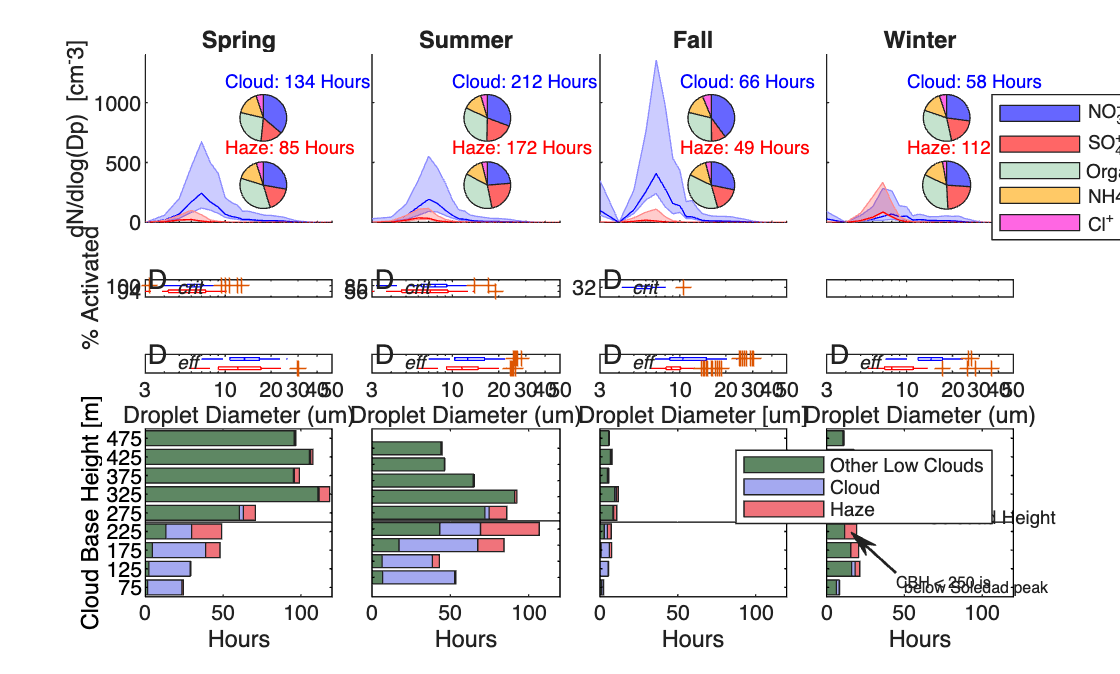

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


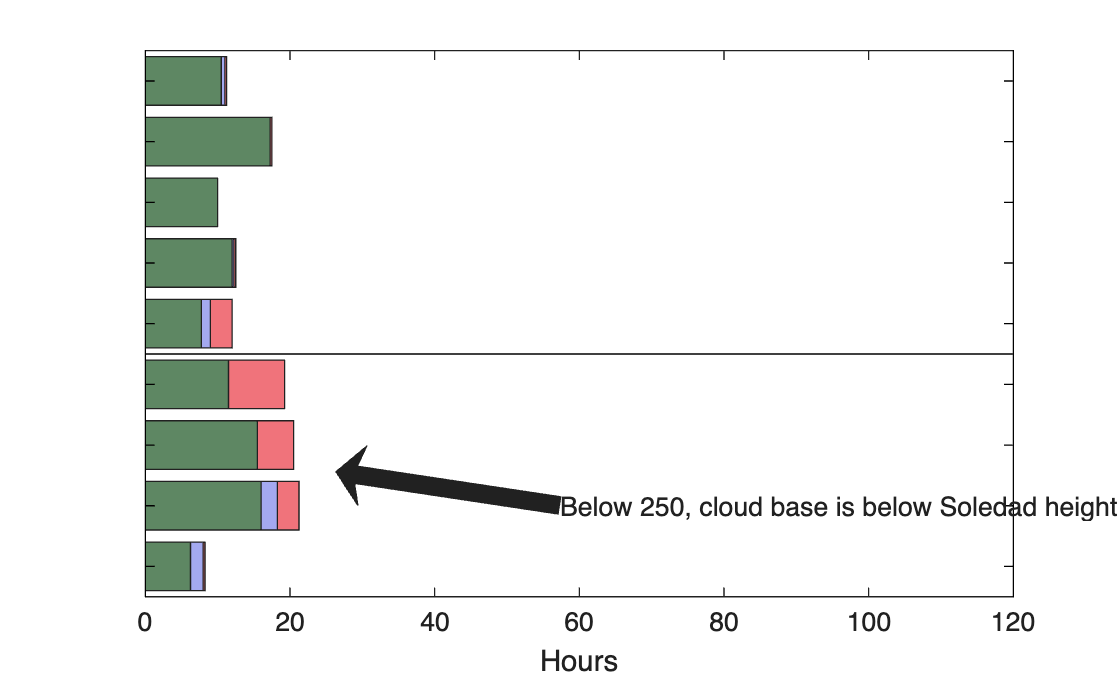

twin = 1×4 table
    Haze_Size_Dist_Hours    Cloud_Size_Dist_Hours    Haze_Crit_Diam_Hours    Cloud_Crit_Diam_Hours
    ____________________    _____________________    ____________________    _____________________

            181                    181.25                     47                      96          


twinspr = 1×4 table
    sprHaze_Size_Dist_Hours    sprCloud_Size_Dist_Hours    sprHaze_Crit_Diam_Hours    sprCloud_Crit_Diam_Hours
    _______________________    ________________________    _______________________    ________________________

             39.75                        40                        12.5                        31.5          


twinsum = 1×4 table
    sumHaze_Size_Dist_Hours    sumCloud_Size_Dist_Hours    sumHaze_Crit_Diam_Hours    sumCloud_Crit_Diam_Hours
    _______________________    ________________________    _______________________    ________________________

             98.75                        99                        19.75                      47.25          


twinfal = 1×4 table
    falHaze_Size_Dist_Hours    falCloud_Size_Dist_Hours    falHaze_Crit_Diam_Hours    falCloud_Crit_Diam_Hours
    _______________________    ________________________    _______________________    ________________________

             31.75                        32                        8.25                       15.75          


twinwin = 1×4 table
    winHaze_Size_Dist_Hours    winCloud_Size_Dist_Hours    winHaze_Crit_Diam_Hours    winCloud_Crit_Diam_Hours
    _______________________    ________________________    _______________________    ________________________

             10.75                        11                         6.5                        1.5           


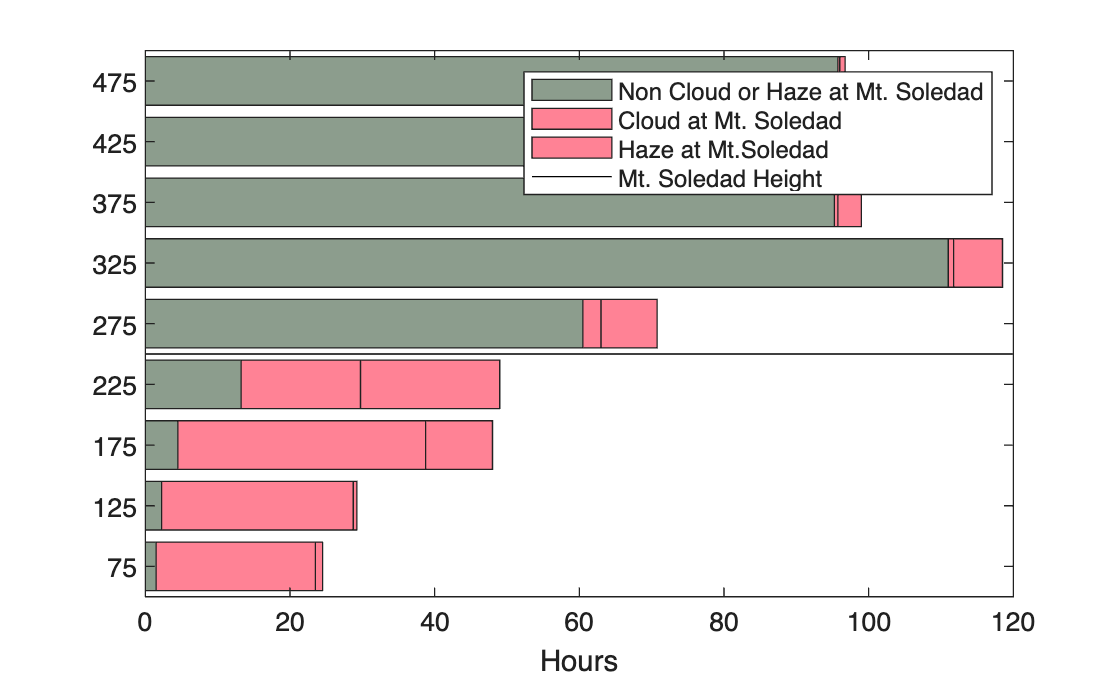

xscale("log")
xlim([3 50])
xticks([3 10 20 30 40 50])
xtickangle(0)
yticks([])
xlabel('Droplet Diameter (um)')
text(3 ,2.20,'D_{\it eff}')

ax8a = nexttile(87,[6,2]);
edges = -250:50:200;
edges1 = 75:50:475;
[N1,edges] = histcounts(250 - CloudBaseHeight(cbhtimewin), edges);
[N2, edges] = histcounts(250 - cloudscbh(ccbhtimewin), edges);
[N3, edges] = histcounts(250 - hazescbh(hcbhtimewin), edges);
C = cat(1, N1, N2);
C = cat(1, C, N3);

bh = barh(flip(edges1), C/4, 'stacked');
set(bh, 'FaceColor','Flat')
bh(1).CData = [0.369, 0.529, 0.388];
bh(2).CData = [0.643, 0.663, 0.941];
bh(3).CData = [0.941, 0.451, 0.482];
xlabel('Hours')
yticklabels([])
ax = gca;
ax.YColor = 'k';
xlim([0 120])
ylim([50 500])

y = [250 250 250 250 250 250 250 250 250];
hold on 
plot(0:50:400,y, 'Color',"black")
hold off

an = annotation("textarrow",[0.80 .76],[.15 .21],String="CBH < 250 is ",FontSize=6);
an.LineWidth = 1;
an.HeadWidth = 7;
text(50,75,'below Soledad peak',Fontsize=6)

legend('Other Low Clouds','Cloud','Haze')

text(65,265,'Soledad Height',FontSize=7)

%%% DSD & LWC Averages

ans = 218.7344

mean(FM120_Nd(springindexcld))
std(FM120_Nd(springindexcld))

ans = 116.6093


mean(FM120_Nd(springindexhaz),'omitmissing')

ans = 24.9362

std(FM120_Nd(springindexhaz),'omitmissing')

ans = 25.0573



mean(FM120_Nd(summerindexcld))

ans = 181.3202

std(FM120_Nd(summerindexcld))

ans = 112.9153

mean(FM120_Nd(summerindexhaz),'omitmissing')

ans = 32.5903

std(FM120_Nd(summerindexhaz),'omitmissing')

ans = 26.8568


mean(FM120_Nd(fallindexcld))

ans = 336.8502

std(FM120_Nd(fallindexcld))

ans = 214.6912

mean(FM120_Nd(fallindexhaz),'omitmissing')

ans = 28.8249

std(FM120_Nd(fallindexhaz),'omitmissing')

ans = 36.7157


mean(FM120_Nd(winterindexcld))

ans = 101.8374

std(FM120_Nd(winterindexcld))

ans = 66.4135


mean(FM120_Nd(winterindexhaz),'omitmissing')

ans = 76.9006

std(FM120_Nd(winterindexhaz),'omitmissing')

ans = 87.3029

mean(FM120_Nd(cloudtimes1),'omitmissing')

ans = 210.2550

std(FM120_Nd(cloudtimes1),'omitmissing')

ans = 141.9431

mean(FM120_Nd(hazetimes2),'omitmissing')

ans = 32.8805

std(FM120_Nd(hazetimes2),'omitmissing')

ans = 36.6064

mean(FM120_LWC_15min(springindexcld),'omitmissing')

ans = 0.1573

std(FM120_LWC_15min(springindexcld),'omitmissing')

ans = 0.1541

mean(FM120_LWC_15min(springindexhaz),'omitmissing')

ans = 0.0077

std(FM120_LWC_15min(springindexhaz),'omitmissing')

ans = 0.0081


mean(FM120_LWC_15min(summerindexcld),'omitmissing')

ans = 0.1237

std(FM120_LWC_15min(summerindexcld),'omitmissing')

ans = 0.1671

mean(FM120_LWC_15min(summerindexhaz),'omitmissing')

ans = 0.0089

std(FM120_LWC_15min(summerindexhaz),'omitmissing')

ans = 0.0091

mean(FM120_LWC_15min(fallindexcld),'omitmissing')

ans = 0.1667

std(FM120_LWC_15min(fallindexcld),'omitmissing')

ans = 0.2321

mean(FM120_LWC_15min(fallindexhaz),'omitmissing')

ans = 0.0062

std(FM120_LWC_15min(fallindexhaz),'omitmissing')

ans = 0.0145


mean(FM120_LWC_15min(winterindexcld),'omitmissing')

ans = 0.1160

std(FM120_LWC_15min(winterindexcld),'omitmissing')

ans = 0.1636

mean(FM120_LWC_15min(winterindexhaz),'omitmissing')

ans = 0.0207

std(FM120_LWC_15min(winterindexhaz),'omitmissing')

ans = 0.0330